d_W =                    0
   5.969529708258343
  11.048080382533234
  15.117807194738749
  18.045280372728243
  19.679403898556291
  19.849219813952633
  18.361071565945686
  14.983635961496034
   9.671085625865762


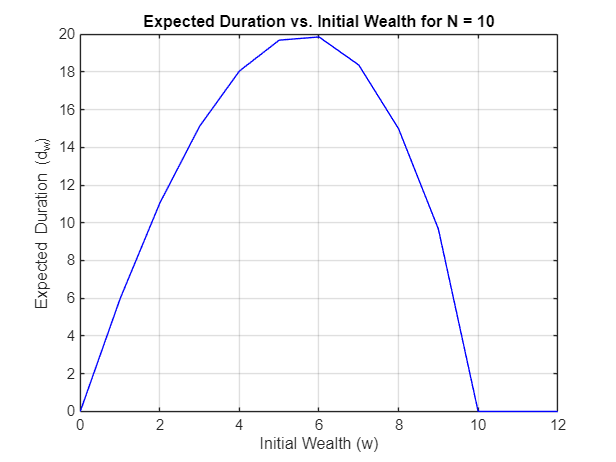

d_W = 1.0e+02 *

                   0
   0.125396758722511
   0.250573685589884
   0.375501704693444
   0.500147894419516
   0.624474978799902
   0.748440751586184
   0.871997424149611
   0.995090887131418
   1.117659874435828


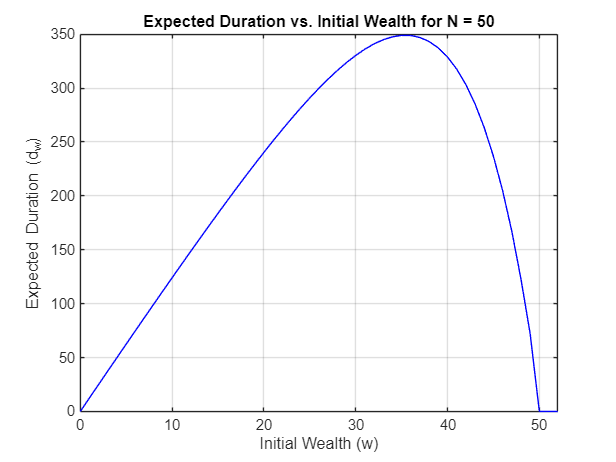

d_W = 1.0e+02 *

                   0
   0.127052174043352
   0.254103468597019
   0.381153767335901
   0.508202938549245
   0.635250833105663
   0.762297282149007
   0.889342094489488
   1.016385053649729
   1.143425914520126


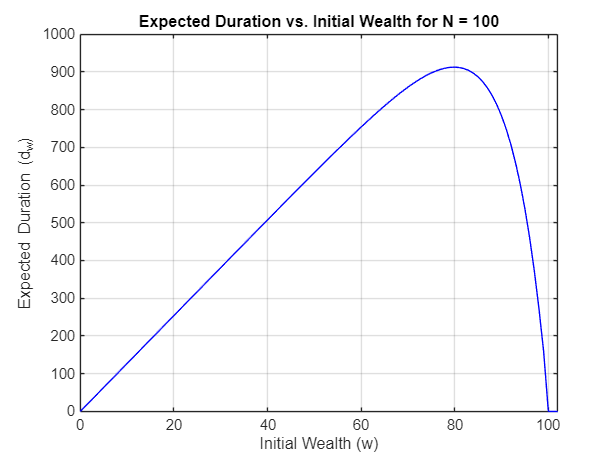

format long

N_values = [10, 50, 100]; 
n = length(N_values); 
p_3 = 1/216;
p_2 = 5/72;
p_1 = 25/72;
q = 125/216; 

for i = 1:n
    N = N_values(i);

P = zeros(N+3, N+3);  

P(1,1) = 1;
P(N+1,N+1) = 1;
P(N+2,N+2) = 1; 
P(N+3,N+3) = 1; 

for row = 2:N
    P(row, row-1) = q; 
    P(row, row) = 0;
    P(row, row+1) = p_1;
    P(row, row+2) = p_2;
    P(row, row+3) = p_3;
end

% Extract Q and R matrices
Q = P(2:N, 2:N);        % Transient-to-transient transitions
R = [P(2:N, 1), P(2:N, N+1), P(2:N, N+2), P(2:N, N+3)];  % Transient-to-absorbing transitions

% Fundamental matrix
I = eye(size(Q));
F = inv(I - Q);
m = length(F(:,1));
c = ones (m, 1);
D = F*c;
D_full = [0; D; 0; 0; 0];

% Extract ruin probabilities
d_W = double(D_full)
    figure;
    plot(0:N+2, d_W, 'b', 'DisplayName', 'd\_W');
    xlabel('Initial Wealth (w)');
    ylabel('Expected Duration (d_w)');
    title(['Expected Duration vs. Initial Wealth for N = ', num2str(N)]);
    grid on;
    xlim([0 N+2])
end